Matlab code for the Course: **Modelling and Simulation Mechatronics System**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

ODE = test2eq();

#### Initialize the solver

%solver = ExplicitEuler();
%solver = Heun3();
%solver = Heun();
%solver = Collatz();
%solver = Midpoint();
%solver = Ralston();
%solver = Ralston3();
%solver = Ralston4();
%solver = RK3();
%solver = RK3_8();
%solver = RK4();
%solver = SSPRK3();
%solver = RadauIA();
%solver = RadauIIA();
%solver = LobattoIIIA();
%solver = LobattoIIIB();
%solver = LobattoIIIC();
%solver = LobattoIIIC_star();
%solver = GaussLegendre4();
%solver = GaussLegendre6();
solver = CrankNicolson();
solver.setODE( ODE );

#### Advance the ODE

DT = 0.1;
T  = 10;
x0 = 0;
y0 = 1;
Zini = [x0, y0];
hh   = [DT,DT/2,DT/4,DT/8,DT/16,DT/32,DT/64,DT/128];
tt1 = 0:hh(1):T;
tt2 = 0:hh(2):T;
tt3 = 0:hh(3):T;
tt4 = 0:hh(4):T;
tt5 = 0:hh(5):T;
tt6 = 0:hh(6):T;
tt7 = 0:hh(7):T;
tt8 = 0:hh(8):T;
Z1  = solver.advance( tt1, Zini);
Z2 = solver.advance( tt2, Zini);
Z3 = solver.advance( tt3, Zini);
Z4 = solver.advance( tt4, Zini);
Z5 = solver.advance( tt5, Zini);
Z6 = solver.advance( tt6, Zini);
Z7 = solver.advance( tt7, Zini);
Z8 = solver.advance( tt8, Zini);

#### Error calculation

err = zeros(1,6);
ex1 = ODE.exact(tt1);
ex2 = ODE.exact(tt2);
ex3 = ODE.exact(tt3);
ex4 = ODE.exact(tt4);
ex5 = ODE.exact(tt5);
ex6 = ODE.exact(tt6);
ex7 = ODE.exact(tt7);
ex8 = ODE.exact(tt8);
err(1) = max(max(abs(Z1-ex1)));
err(2) = max(max(abs(Z2-ex2)));
err(3) = max(max(abs(Z3-ex3)));
err(4) = max(max(abs(Z4-ex4)));
err(5) = max(max(abs(Z5-ex5)));
err(6) = max(max(abs(Z6-ex6)));
err(7) = max(max(abs(Z7-ex7)));
err(8) = max(max(abs(Z8-ex8)));

#### Initialize the solver class

err

err = 	1.0e+02 *

   5.046949019632447   1.267475646216663   0.317222586354837   0.079327672258223   0.019833293429401   0.004958409298015   0.001239607695206   0.000309902259178


hh

hh =    0.100000000000000   0.050000000000000   0.025000000000000   0.012500000000000   0.006250000000000   0.003125000000000   0.001562500000000   0.000781250000000


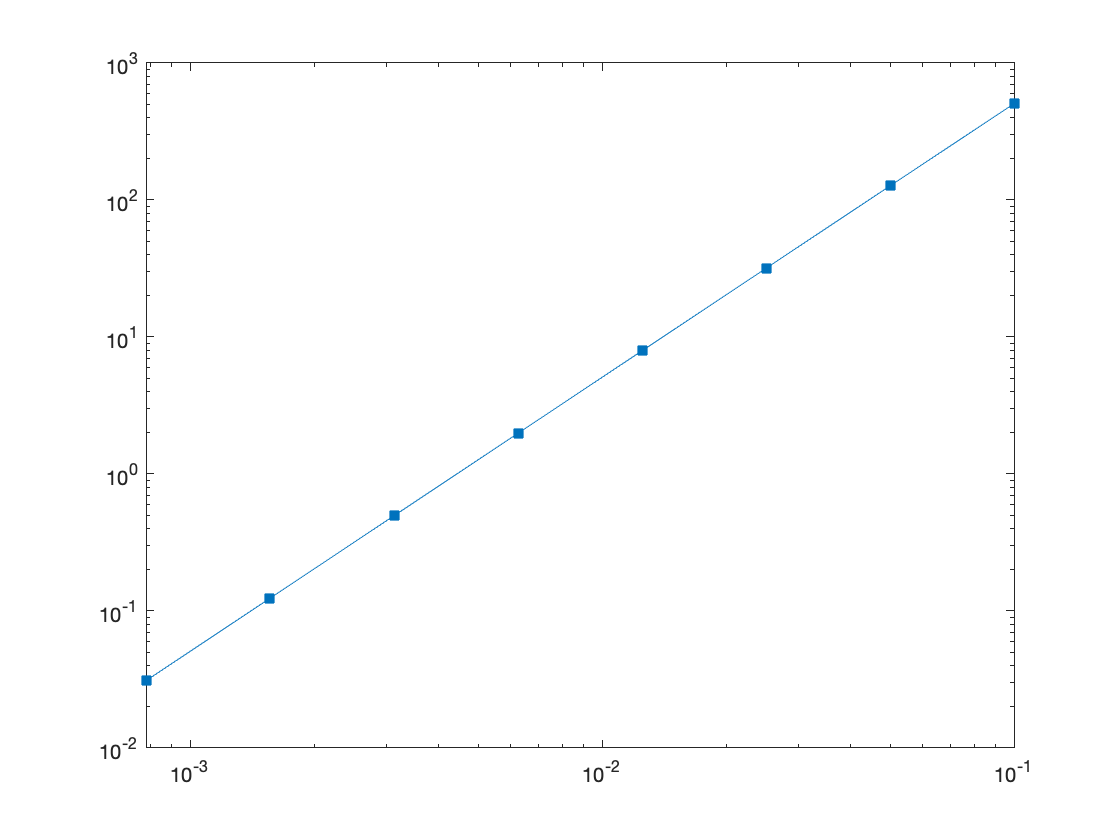

loglog(hh,err,'-s','MarkerFaceColor',[0 0.447 0.741]);

(log(err(1:end-1)./err(2:end))./log(hh(1:end-1)./hh(2:end))).'

ans =    1.993453486746590
   1.998390626792467
   1.999599373894274
   1.999899951016622
   1.999974994552156
   1.999993749391136
   1.999998438714832



%plot(tt1,Z1(1,:),tt1,ex1(1,:))
%plot(tt6,Z6(2,:),tt6,ex6(2,:))